# Neural Networks

## What are neural networks?

**Neural networks** are a set of algorithms that are inspired by neural circuits in the brain. These algorithms can be computationally intensive, and have recently exploded in popularity due to advances in computing technology, such as GPUs that can perform computations in parallel with the CPU. 

Neural networks generally work by taking linear combinations of predictors to engineer new representations of our features. Non-linear functions are applied to the new features to model the potential non-linearity in the dataset. This family of learning methods are really flexible, and can be used for classification and regression problems.

### Modern applications of neural networks

Neural networks have been applied to several real-world problems, from[ determining medical diagnoses by classifying images](https://towardsdatascience.com/medical-diagnosis-with-a-convolutional-neural-network-ab0b6b455a20) to [training a self driving car](https://towardsdatascience.com/deep-learning-for-self-driving-cars-7f198ef4cfa2) to [biomedical text mining for extracting relevant patient information](https://medium.com/@Petuum/applying-neural-networks-to-biomedical-text-mining-fe655270c12). The main advantages of neural networks are the following:

- They are highly non-linear models that can detect nonlinear relationships and interactions between predictors/response variables

- The mathematics underpinning neural networks relies less on statistical assuptions we usually impose in other models

- Neural networks are modular, and many architectures are available to model different problems

### Common components and notation of a neural network

There are [several flavors of neural network architectures](https://medium.com/cracking-the-data-science-interview/a-gentle-introduction-to-neural-networks-for-machine-learning-d5f3f8987786), each one having their own advantages and disadvantages for solving different problems. The diagram below illustrates a **feed-forward neural network**, where information flows forward from the input to the output, and no information feeds back into the network. 

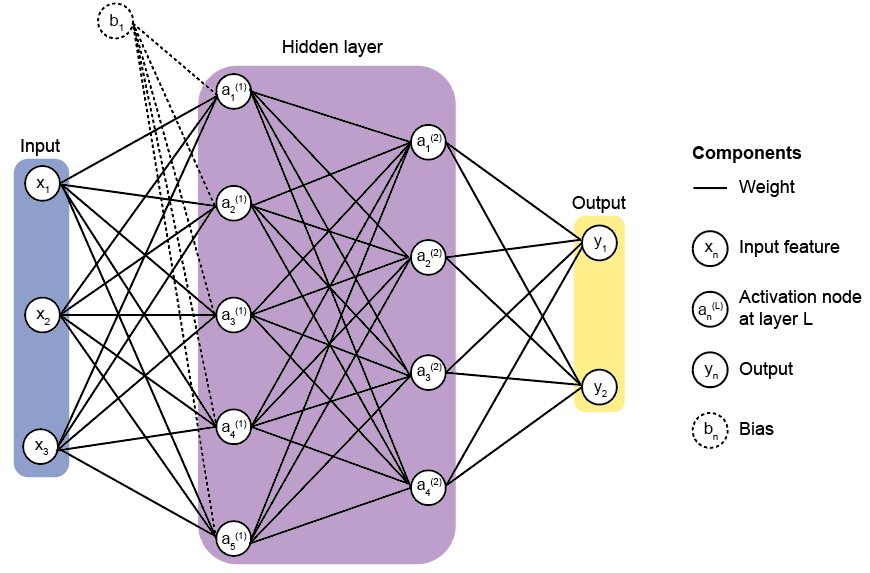

#### The input layer

Each node in the **input layer** represents a feature in the training data ($X_{\textrm{train}}$). Each edge corresponds to a **weight** vector. Further, we can choose to add more flexibility into the model by introducing some **bias** values. When we compute values that are propagated to the activation node, we'll be solving equations that are analagous to the linear regression expression, where we will solve equations that look like $Z\;=\;X\cdot \textrm{weights}+\textrm{bias}$.

#### The hidden layer(s)

The hidden layer is where the new values are stored from taking linear combinations of features from the input layer and applying non-linear transformations. These nodes are are known as **activation nodes**, and each activation node in the hidden layer represents a single new feature. 

A neural network with a single hidden layer is known as a **shallow neural network**. However, we can add more complexity in the model by adding more hidden layers and more activation nodes. Neural networks with more than 1 hidden layer are known as **deep neural networks** (DNNs), and the application of DNNs is known as **deep learning**. 

#### **The output layer**

From the last hidden layer, the final values are propagated to the **output layer**. In this layer, we can use rules to turn these values into labels for a classification problem, or keep the probabilities in a regression problem. 

**To illustrate the main concepts underpinning neural networks for the next two lectures, we'll code up a shallow feedforward neural network from scratch.** There are three main phases in a feedforward neural network that we'll go over in depth:

- Fitting the model in **forward propagation**

- Evaluating the performance of the trained using a **cost function**

- Tuning model parameters using **backward propagation and gradient descent**

## Step 1: Constructing new features using forward propagation

The training phase of a neural network is called [forward propagation](https://towardsdatascience.com/forward-propagation-in-neural-networks-simplified-math-and-code-version-bbcfef6f9250)**. **It consists of iteratively computing linear combinations of the input fed into each layer, followed by a non-linear transformation of the combined features. This is repeated for each hidden layer until we reach the output layer.

### Computing linear combinations of features 

Let's first use an artificial dataset to demonstrate what forward propagation does to our data. The example below uses a training dataset $X$ with 20 observations and 3 predictor variables.  

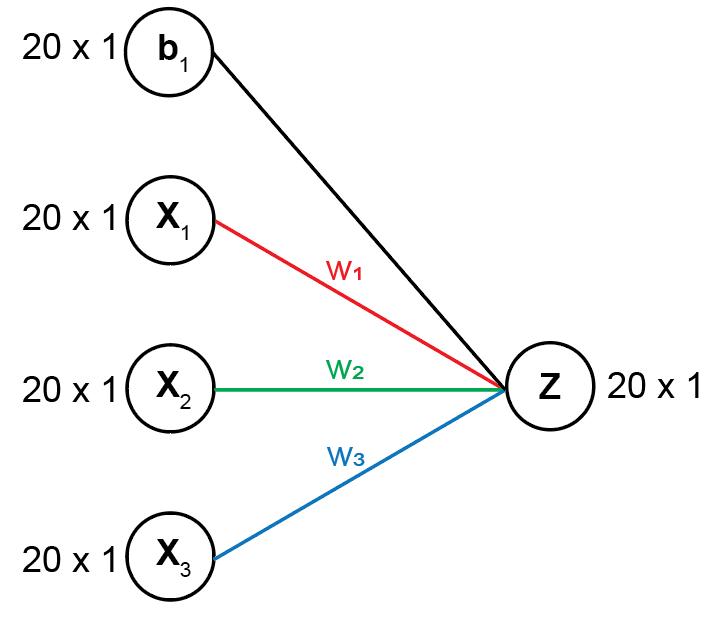

The formula to take a linear combination of predictors has the same structure as the linear regression equation:


$$Z=Xw^T +b$$


Our problem in this step is slightly different from a linear regression problem in that we are solving for the output $Z$ rather than using $X$ and $Z$ to estimate our coefficients. However, we have the same global objective of trying to estimate the two parameters of interest, which we do in later steps: 

- The **weights** ($w$), which is equivalent to the regression coefficients $\beta$

- The **bias** ($b$) values, which is equivalent to the intercept $\beta_0$. 

#### Impact of weights on the new feature `Z` generated by the neural network 

For now, let's see how the two parameters $w$ and $b$ affect the solution $Z$, and then plot the relationship between $X$ and $Z$. We'll take the linear combinations with 1 to 3 weights and biases of different values. 

% Set a fixed random number generator (rng) for reproducibility
rng(2);

Invalid expression. Check for missing or extra characters.

X = %
b = %

#### Solution using 1 weight value

The following network diagram using 1 weight value is shown below:

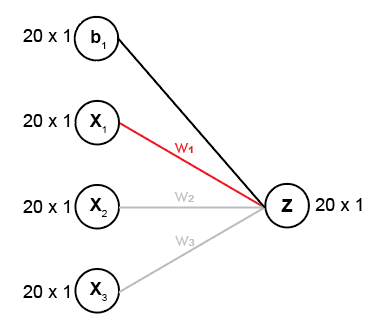

Which is equivalent to solving the following set of equations:


$$Z=X_1 w_1 +b$$


% Weight vectors
w = % Only 1 weight
Z1 = %

Let's now plot the relationship between each feature in $X$ and the output $Z$. 

figure; gray = [200, 200, 200] / 255; 
subplot(1, 3, 1); scatter(X(:, 1), Z1, 'red', 'filled')
xlabel('X_{1}');  ylabel('Z'); set(lsline, 'color', 'r')
subplot(1, 3, 2); scatter(X(:, 2), Z1, [], gray, 'filled')
xlabel('X_{2}');  lsline
subplot(1, 3, 3); scatter(X(:, 3), Z1, [], gray, 'filled')
xlabel('X_{3}');  lsline

Note that the slight positive relationship between $X_2$ or $X_3$ and $Z$ is not meaningful, but is an artificact from the small number of observations we used to make $X$ and random chance.

#### Solution using 2 weight values

If we include two weights, the network will look like the following diagram:

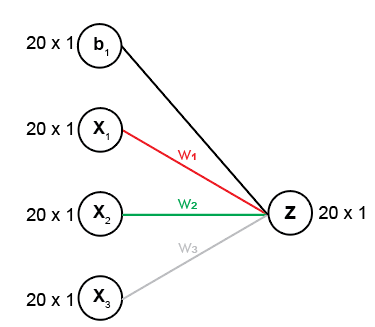

And the system of equations will look like the following:


$$Z=X_1 w_1 +X_2 w_2 +b$$


You will notice that there is a stronger correlation between the new feature $Z$ and $X_2$, as it is assigned a higher weight.

w = % 2 weights only
Z2 = %
% Make plot
figure; green = [34, 139, 34] ./ 255;
subplot(1, 3, 1); scatter(X(:, 1), Z2, 'red', 'filled')
xlabel('X_{1}');  ylabel('Z'); set(lsline, 'color', 'r')
subplot(1, 3, 2); scatter(X(:, 2), Z2, [], green, 'filled')
xlabel('X_{2}');  set(lsline, 'color', green)
subplot(1, 3, 3); scatter(X(:, 3), Z2, [], gray, 'filled')
xlabel('X_{3}');  lsline

#### Solution using 3 weight values

Finally, let's include a fully connected hidden layer with all 3 weights.

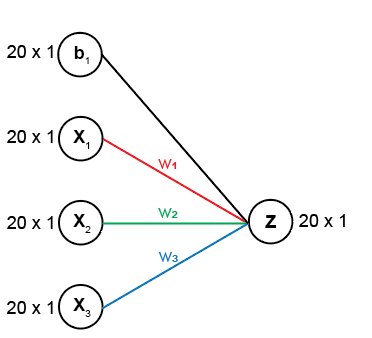

Where the complete set of linear equations to solve will be:


$$Z=X_1 w_1 +X_2 w_2 +X_3 w_3 +b$$


w = % All 3 weights
Z3 = %
% Make plot
figure; blue = [30, 144, 255] ./ 255;
subplot(1, 3, 1); scatter(X(:, 1), Z3, 'red', 'filled')
xlabel('X_{1}');  ylabel('Z'); set(lsline, 'color', 'r')
subplot(1, 3, 2); scatter(X(:, 2), Z3, [], green, 'filled')
xlabel('X_{2}');  set(lsline, 'color', green)
subplot(1, 3, 3); scatter(X(:, 3), Z3, [], blue, 'filled')
xlabel('X_{3}');  set(lsline, 'color', blue)

We have a new complex feature that is positively correlated with $X_1$ and $X_2$, but negatively correlated with $X_3$,

#### Takeaways

As you can see with the boxplot above, different combinations of weights dramatically the distribution of the final computed predictor `Z`, and creates more complex features`.` Thus, the weights are a really important parameter to tune in the model.

#### How do we initialize the weights and biases in practice?

Without knowing the true relationship between the predictor and response variables, we need to initialize the weight and bias parameters somehow. It turns out that[ intializing neural networks with small and random values for w and b is a better way](https://machinelearningmastery.com/why-initialize-a-neural-network-with-random-weights/) to train these parameters than setting them to all zero or one. We'll explore this idea further later in the lecture.

### Non-linear transformations using an activation function

In this section, we'll discuss different ways to add non-linearity into the computed variable `Z`, and the advantages / disadvantages of each method.

#### The sigmoid activation function

One way to transform the data is to use the sigmoid activation function (aka logit transformation) to transform our data into probabilities with values ranging from [0, 1]. The formulation of the sigmoid activation function is:


$$\textrm{sigmoid}\left(Z\right)=A=\frac{1}{1+e^{-Z} }$$


And the shape of the sigmoid distribution is shown below:

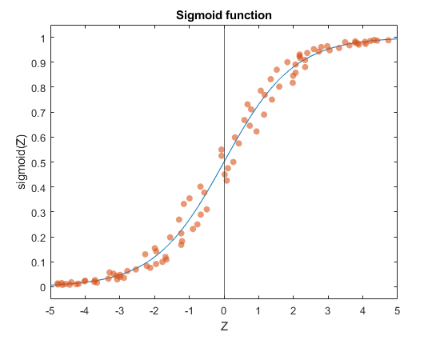

To access all the activation functions described in this lecture, we can use the `activationFnc` script provided in the project folder (documentation described below) to transform our values.

**Applying the sigmoid activation function to **`Z`

Let's see what happens when we apply the sigmoid activation function element-wise to the three Z vectors we computed in the previous section from introducing different weights.

% Compute y using the Z1 cell array containing the results from using different w values
Z = % Store all Z values in single array to perform 1 computation
A = % Scaled from 0 -> 1 using sigmoid activation function

% Plot 3 sigmoid curves
figure;
for i = 1:size(A, 2) % Make scatter plot of the sigmoid curves
    subplot(1, 3, i)
    scatter(Z(:, i), A(:, i), ... 
            'filled', 'o', 'MarkerFaceAlpha', 0.6, ... 
            'jitter', 'on', 'jitterAmount', 0.5);       
    xlabel(strcat('Z', string(i))); ylabel(strcat('sigmoid(Z', string(i), ')'));
    ylim([-0.05, 1.05]); xlim([-10, 10]);
end

Applying the sigmoid activation function transforms our each $Z$ vector scales the data from $\left\lbrack 0,1\right\rbrack$ and also generates the characteristic sigmoid curve. This feature of the sigmoid activation function is especially useful for binary classification.

### Rectified linear units (ReLUs) 

While the `Sigmoid` activation function is easy to interpret and is simple to apply, there are issues with using it as an activation function:

- With each iteration, the $e^{-Z}$ term in the `sigmoid` function becomes infinitesimally small. When correcting our parameters in back propagation (covered in the next section), correcting these extremely small values result in slower updates. This is called the **vanishing gradient problem**, and is an issue when it comes to optimizing neural network parameters using gradient descent.

- Further, our values are between 0 and 1. This is not really useful for regression problems.

Thus, people have been turning to the ReLU as the preferred activation function, especially for more complex neural network architectures. The formulation of the **ReLU** is shown below, and is really simple:


$$\textrm{ReLU}\left(z\right)=\left\lbrace \begin{array}{cc}
z & \textrm{if}\;z>0\\
0 & \textrm{if}\;z\le 0
\end{array}\right.$$


This basically sets negative values to 0, while leaving the original transformed value intact. The ReLU activation function has the following non-linear distribution shape:

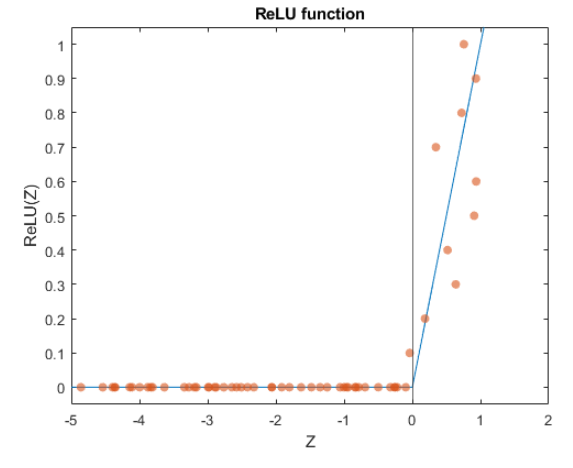

The ReLU has gained popularity in recent years because it takes care of the problems faced by the Sigmoid activation function, such as:

- The correction term in back propagation is not infinitesimally small. This rectifies the vanishing gradient problem.

- Because only a few neurons would be activated (negative values are all 0), this makes the model more efficient.

### Leaky rectified linear units (Leaky ReLUs) 

The ReLU does have its own set of problems, such as handling real negative values (since they're set to 0, the model will essentially ignore these values). 

There is an improved method of the ReLU: the** leaky ReLU**! Instead of setting to value to 0 for negative numbers, we'll scale the negative values using a small weight (usually this weight, which we'll denote as epsilon ($\varepsilon$) is set to 0.01). This will cause a smaller gradient to flow for the negative values, and thus improves our performance with negative numbers.

The formulation for the leaky ReLU is


$$\textrm{Leaky}\;\textrm{ReLU}\left(Z\right)=\left\lbrace \begin{array}{cc}
z & \textrm{if}\;z\;\textrm{is}\;\textrm{positive}\\
\varepsilon \cdot z & \textrm{if}\;z\;\textrm{is}\;\textrm{negative}
\end{array}\right.$$


The leaky ReLU has the following distribution shape:

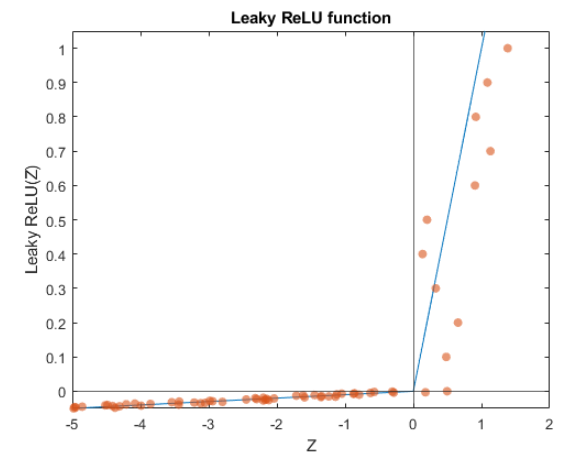

Now that we have covered a single round of combing features and adding non-linearity to the combined features, we have the tools to run a full round of forward propagation. 

### A single round of forward propagation

Let's now put all of these concepts together to run 1 round of forward propagation with **no hidden layer** using a breast cancer dataset built into MATLAB. Without the hidden layer, we're training a model that is essentially a logistic regression model.  

#### Description of breast cancer dataset

The dataset can be called using the `load cancer_dataset `command, and a comprehensive description of the dataset can be found by typing in `help cancer_dataset`. 

- The input is a matrix of 9 features from 699 biopsies. The features include attributes such as adhesion, cell size, and cell shape. These are stored in the `cancerInputs` variable. 

- The `cancerTargets` variable is a 2 x 699 matrix, where the first column corresponds to benign, and the the second column corresponds to malignant. Thus, we will perform binary classification.

clear all;
load cancer_dataset.mat

% View input dataset. Rows = features. Columns = observations
data = array2table(cancerInputs, ...
    "RowNames", {'Clump thickness', 'Uniform Cell size', ...
    'Uniform Cell shape', 'Adhesion', 'Single cell size', ...
    'Bare nuclei', 'Bland chromatin', 'Normal nucleoli', ...
    'Mitoses'})
% View target dataset. Rows = targets. Columns = observations
target = array2table(cancerTargets, ...
    "RowNames", {'Benign', 'Malignant'})

The model schematic and an overview of the computations we will be performing is shown below. 

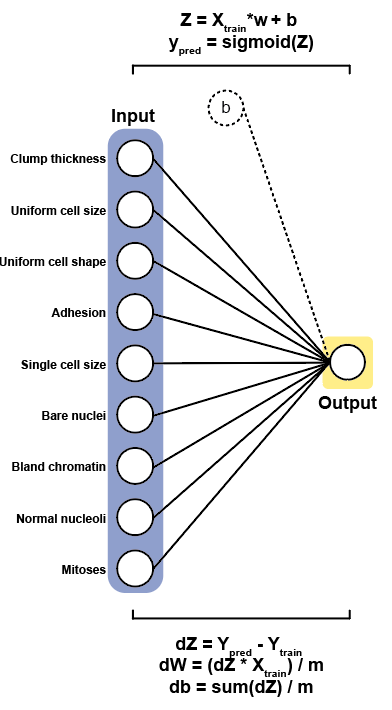

Let's now create the variables we'll need to train and test the model:

% Set seed for reproducibility
rng(2);

% Initialize params for trainTestSplit
trainingSize = 0.8; randomstate = 2;

% Split the dataset into training and test sets.
[Xtrain, Ytrain, Xtest, Ytest] = ...
    trainTestSplit(cancerInputs', cancerTargets(1, :)', ...
    trainingSize, randomstate);

% Standardize the dataset with mean = 0 and standard deviation = 1. 
mu = mean(Xtrain); sigma = std(Xtrain);
Xtrain = zscore(Xtrain, mu, sigma); Xtest = zscore(Xtest, mu, sigma);

#### Intialize variables needed to run forward propagation

Our objective is to compute 1 output vector for the binary classification problem. Further, we're going to use the sigmoid activation function, which is essentially equivalent to performing logistic regression.

% Intialize the hyperparameters 
numberOutputNodes = 1; actFnc = 'Sigmoid';

% Intialize the weights and biases. w size should be number of features x number of activation nodes
w = randn([size(Xtrain, 2), numberOutputNodes])
% b size should be number of observations in training data x 1
b = randn([size(Xtrain, 1), 1])

#### Forward propagation

Let's now run forward propagation from the input layer to the output layer:

Z = Xtrain * w + b
ypred = activationFnc(Z, actFnc)

Now we need to now see how well our model performed using a cost function.

## Step 2: Evaluating the model fit using the cost function

Next, we need to evaluate how well our model has performed in it's initial pass through using a cost function. Because we are performing a binary classification problem, we can use the **cross-entropy cost function.**

### **Cross-entropy cost function**

Recall the formulation for the Cross-Entropy cost function:


$$J=-\frac{1}{m}\sum_{i=1}^m \left\lbrack -{y_{\textrm{train}} }^{\left(i\right)} \log \left(y_{\textrm{pred}}^{\left(i\right)} \right)-\left(1-{y_{\textrm{train}} }^{\left(i\right)} \right)\log \left(1-y_{\textrm{pred}}^{\left(i\right)} \right)\right\rbrack$$


where $m$ are number of observations, $y_{\textrm{train}}$ is the response variable, and $y_{\textrm{pred}}$ is a vector of the predicted value from forward propagation. 

The **cost** value (`J)` can be computed using the `costFunction` function provided. The docstring is provided below:

lossFunction = 'Log-Loss';
J = costFunction(Ytrain, ypred, lossFunction)

Now that we have a cost value, we can start to optimize our neural network algorithm using backward propagation.

## Step 3: Optimizing `w` and `b` parameters using backward propagation

After computing the cost, we know how good or how bad our model performed overall. In neural networks, we need to tell the algorithm how to adjust the weight and bias parameters so that the cost goes down in the next iteration,  until we reach a stable minimum cost value. This process is called **back propagation**, and the optimization algorithm we use to update the weights and the biases is **gradient descent**. 

### Finding the gradients dW and db using back propagation

The objective of back propagation is to determine how much we should change `w` and `b` such that we minimize the cost. Thus, we need to find an expression that allows us to relate the cost back to the parameter`. `The **gradient**, or the values from solving partial differential equations of the cost with respect to W ($\frac{\vartheta J}{\vartheta W}$) and b ($\frac{\vartheta J}{\vartheta b}$) will tell us how much error a specific activation node contributes to the overall model error.

#### Intuition for back propagation 

Formulated below are the expressions needed to solve $\frac{\vartheta J}{\vartheta W}$ and  $\frac{\vartheta J}{\vartheta b}$ for each layer:

$\frac{\vartheta J}{\vartheta W}$ = $\frac{\vartheta J}{\vartheta y}\cdot \frac{\vartheta y}{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta W}$ 

$\frac{\vartheta J}{\vartheta b}$ = $\frac{\vartheta J}{\vartheta y}\cdot \frac{\vartheta y}{\vartheta Z}\cdot \frac{\vartheta Z}{\vartheta b}$ 

Let's consider the gradient $\frac{\vartheta J}{\vartheta W}$ (the same logic applies for $\frac{\vartheta J}{\vartheta b}$) and work backwards from the output layer to the input layer. There are three places where the model can go wrong: 

- From the output layer to the hidden layer ($\frac{\vartheta J}{\vartheta y}$). A natural expression to compute this error is $Y_{\textrm{pred}} -Y_{\textrm{train}}$.

- From the activation function ($\frac{\vartheta y}{\vartheta Z}$). This expression changes with different activation functions.

- From computing the new feature $Z$ with the weight $w$ ($\frac{\vartheta Z}{\vartheta W}$).

As you can see, each layer is chained together. Fortunately, because we know how the network is connected, we can figure out partial differential terms that will connect the cost to any given weight or bias parameter that needs to be adjusted to lower the cost. 

We won't go over the derivation for each term, but in practice, we would work these differential equations individually and use the chain rule to compute the gradients. 

#### Derivative terms for back propagation in a logistic regression model

The following set of equations are used in our logistic regression model to compute the gradients for each parameter (denoted as `dw` and `db). `Because we're comparing our predictions directly against our training set, we don't have to compute the error from the activation function.


$$\textrm{dZ}=Y_{\textrm{pred}} -Y_{\textrm{train}} \;$$



$$dW=\textrm{dZ}\cdot {X_{\textrm{train}} }^T \cdot \frac{1}{m}$$



$$\;\textrm{db}=$$
 
$$\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ}\right)$$


### Back propagation 

Now let's codify the expressions above to run back propagation. First we need to compute the error from the outermost layer: 


$$\textrm{dZ}=Y_{\textrm{pred}} -Y_{\textrm{train}} \;$$


dZ = ypred - Ytrain

Next, we have to compute how much error our weights contributed to the overall error in proportion to `dZ.` $\frac{1}{m}$ normalizes our error term by the number of observations in the dataset: 


$$dW=\frac{1}{m}\left(\textrm{dZ}\cdot {X_{\textrm{train}} }^T \right)$$


m = size(Xtrain, 1)          % m = number of observations in training set
dW = (1/m) .* (Xtrain' * dZ)

Finally, we compute the error in the bias term, which is the sum of the errors from the output layer normalized based on the number of observations in the data: 


$$\;\textrm{db}=$$
 
$$\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ}\right)$$
 

db  = (1/m) .* sum(dZ, 2)

We have just completed the first iteration of back propagation, which relates the cost value J back to the parameters w and b. The last step we need to do is to update the weights and biases. We can do that using the **gradient descent** optimization algorithm.

### Optimizing parameters `W` and `b` using gradient descent

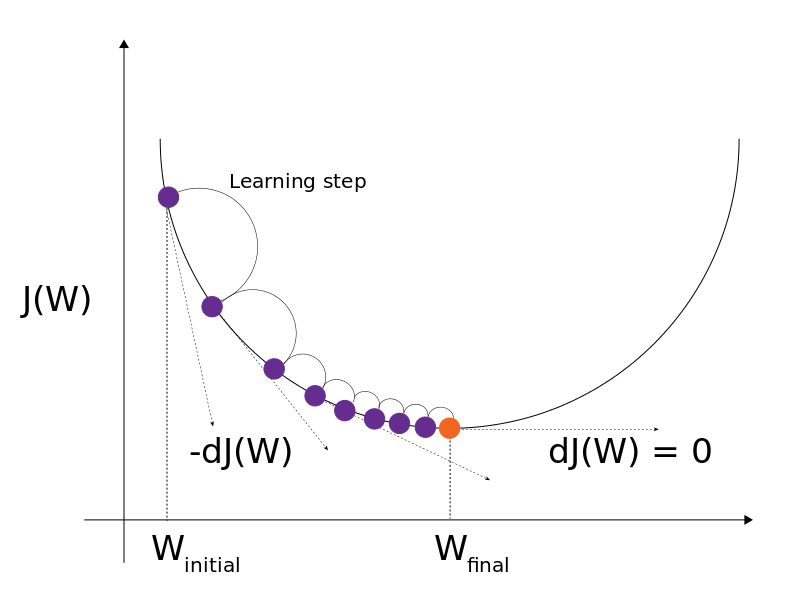

The objective of gradient descent is to minimize the cost by updating the parameters in the model. Because we have two parameters **W** and **b**, we have two update equations:


$$\begin{array}{l}
\mathrm{W}=\mathrm{W}-\left(\textrm{learning}\;\textrm{rate}\cdot \textrm{dW}\right)\\
\mathrm{b}\;\;=\mathrm{b}\;\;-\left(\textrm{learning}\;\textrm{rate}\cdot \textrm{db}\right)
\end{array}$$
 

where the learning rate hyperparameter is a positive constant value that controls how fast we move along the gradient. Further, `dW` and `db` are the gradients we computed from back propagation. We can perform gradient descent for `w` and `b` using the code below:

learning_rate = 0.05;
w = w - (learning_rate .* dW)
b = b - (learning_rate .* db)

## Optimizing the logistic regression model using forward and backward propagation

Now that we did a single pass of forward and backward propagation with our logistic regression model, let's make an algorithm that uses all the components we described so far to optimize the two parameters `w` and `b` after 500 iterations. Note that in machine learning jargon, an iteration of both forward and backward prop is called an **epoch. **First, let's re-initialize the variables we used in forward propagation, cost computation, and backward propagation:

% Re-intialize variables
epoch = 500; learning_rate = 0.05; numberOfOutputNodes = 1; % Hyperparameters
m = size(Xtrain, 1);                                         % Normalizing scale
actFnc = 'Sigmoid';                                          % Sigmoid activation function
w = randn([size(Xtrain, 2), numberOfOutputNodes]);           % Number of Xtrain features x number of responses
b = randn([size(Xtrain, 1), 1]);                             % Number of observations

Next, we need to write an expression that will allow us to loop all three steps several times, while simultaneously updating the weights and biases after each iterations. 

for i = 1:epoch                                     % Iterate forward and backward propagation + gradient descent 500 times
    Z = Xtrain * w + b;                             % 1. Forward propagation
    ypred = activationFnc(Z, actFnc);
    
    J(i) = costFunction(Ytrain, ypred, 'Log-Loss'); % 2. Cost evaluation -> store the costs for plot
    %disp(strcat(string(i), 'itera')
    disp(J(i))
    
    dZ = ypred - Ytrain;                            % 3. Back propagation
    dW = (1/m) .* (Xtrain' * dZ); 
    db = (1/m) .* sum(dZ, 2);
     
    w = w - (learning_rate .* dW);                  % Gradient descent for iterative update
    b = b - (learning_rate .* db);
end

### Visualizing the model error from the cost curve

This is how we obtain the final trained model from forward and backward propagation. Note that we saved the cost for both class predictions during our `for` loop. Let's now plot the cost curve using the cost values `J` against the number of epochs to see how much the error decreased over each training period:

% Cost curve
figure; plot(1:epoch, J, 'color', 'r');
title('Cost with learning rate = 0.05'); 
xlabel('Number of epochs'); ylabel('Cost (J)');

The cost value of using this logistic regression model with forward and backward propagation begins to approach a minimum value around 500 epochs, and has the shape of the **negative binomial distribution**, which is expected from logistic regression. 

How do the probability values we predict look?

ypred'

### Label encoding for classification

Now that we have our probabilities, we can evaluate the model's performance. But first, we need to turn these probabilities into labels. This process is known as **label encoding**. 

The method shown below has used a probability of 50% (p = 0.5) as the decision boundary for predicting whether or not the same is a malignant sample.

% Label encoding for classification
ypred(ypred >= 0.5) = 1; % If the probability is greater than 50%, set it to malignant class 
ypred(ypred < 0.5)  = 0; % Otherwise, set it to benign class

## Logistic regression benchmarking

### Training accuracy

We can compute the binary clasification hold-out accuracy using the **zero-one loss** formulation:


$$\begin{array}{l}
\textrm{Accuracy}=1-L\left(y,y_{\textrm{pred}} \right)\\
\textrm{Accuracy}=1-\textrm{mean}\left(\textrm{abs}\left(y_{\textrm{pred}} -y\right)\right)
\end{array}$$


% Compute training accuracy using mean absolute deviation
train_accuracy = 1 - (sum(abs(ypred - Ytrain)) / m)

### Holdout accuracy

The training accuracy alone is not a great measure to evaluate our model. We should also compute the holdout and k-fold cross validation accuracies. 

% Used trained weights to compute ypred
clear ypred; Z = Xtest * w;
ypred = activationFnc(Z, actFnc);

% Label encode the predicted values from the test set
ypred(ypred >= 0.5) = 1; % If the probability is greater than 50%, set it to malignant class 
ypred(ypred < 0.5)  = 0; % Otherwise, set it to benign class

#### Confusion matrix of the holdout

To visualize the model's performance, let's plot the confusion matrix of the holdout:

% Create confusion matrix
cm = confusionmat(Ytest, ypred);
figure; labels = {'Malignant', 'Benign'};
title('Logistic regression hold out accuracy');
confusionchart(cm, labels)

#### Model metrics of the holdout

And let's compute other model statistics that we may be interested in:

TP  = cm(1, 1); FP = cm(1, 2); FN = cm(2, 1); TN  = cm(2, 2);
malignant_precision = (TP) / (TP + FP)
malignant_recall    = (TP) / (TP + FN)
benign_precision    = (TN) / (TN + FP)
benign_recall       = (TN) / (TN + FN)
average_accuracy    = sum(diag(cm)) / sum(cm, 'all')

### Cross validation accuracy

The following cross validation schematic shown below was used to compute the cross validation accuracy.

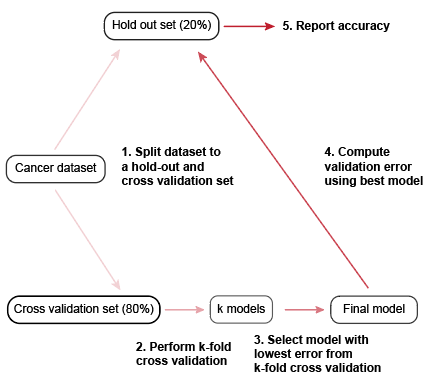

**Why perform cross validation this way?** This cross-validation with the holdout ensures that the final model we output never sees the test set. This ensures that we have a really decent estimate of the parameters that is generalizable across several datasets.

To save space, the procedure described previously has been refactored into the `crossValidate` function. The documentation for the function is shown below:

Let's now run 5-fold cross validation accuracy. We'll compare our results with the shallow neural network later in the section. 

kfold = 5; type = 'Logistic'; hyperparameters = {};

% Run cross validation
Summary = crossValidate(Xtrain, Ytrain, Xtest, Ytest, ...
                            hyperparameters, kfold, type)

#### Cross validation confusion matrix

figure; title('Confusion matrix from 10-fold cross validation');
labels = {'Malignant', 'Benign'};
confusionchart(Summary.cm, labels)

## Back to the shallow neural network

Now that we constructed a logistic regression model that performs forward and backward propagation, let's return back to the original model we wanted to build - the neural network with 1 hidden layer. We'll set the number of nodes in the hidden layer equal to 2. The schematic for the model we're training and a summary of the computations performed is shown below:

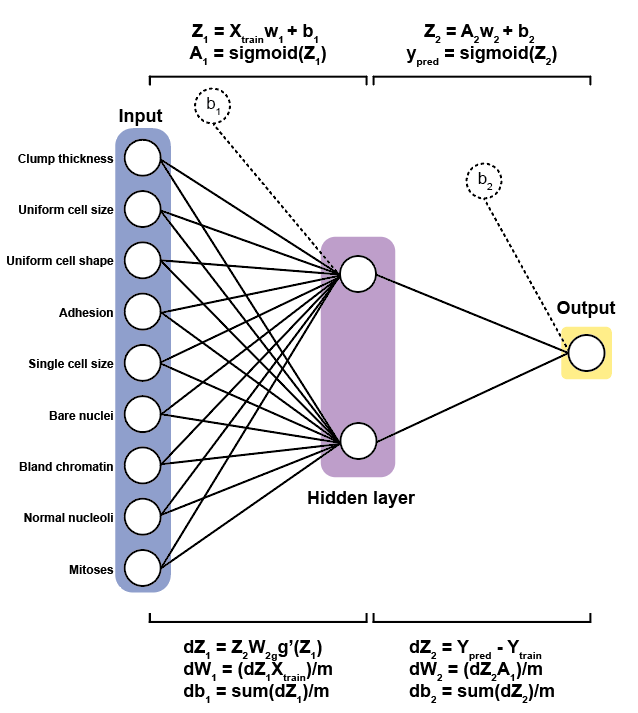

### Forward propagation

First let's initialize some parameters and hyperparameters. This time, we'll have 4 parameters to compute: weights and biases between input and hidden layer `(w1, b1)`, and weights / biases between hidden and output layer `(w2, b2)`. 

% Intialize the hyperparameters 
numberOfHiddenNodes = 2; actFnc = 'Sigmoid';

% Intialize the weights and biases. 
w1 = randn([size(Xtrain, 2), numberOfHiddenNodes]) % Size of w1 should be number of features x number of hidden nodes
b1 = randn(size(Xtrain, 1), 1)                     % Size should be number of obs x 1

#### 1 forward step from the input layer to the hidden layer

Note that Z1 and A1 are the linear combination of features and transformed features. Because we have 2 activation nodes, we have 2 engineered features.

Z1 = Xtrain * w1 + b1
A1 = activationFnc(Z1, actFnc)

#### The last forward step from the hidden layer to the output layer

Now that we have the transformed values stored in `A1`, we'll use this data and transform it 1 more time using forward propagation. 

First, let's initialize the weights and biases. Note that because we're trying to output a single vector of predicted values, the column size of the weights must also be the same size as Ytrain.

w2 = randn([size(A1, 2), size(Ytrain, 2)]) % Size of w2 needs to be number of features in A1 x number of classes
b2 = randn(size(A1, 1), 1)                 % Size of b2 needs to be number of obs x 1

Finally, let's move 1 forward step from the hidden layer to the output layer. We'll use the same activation function we used in the previous step.

Z2 = A1 * w2 + b2

Because this is the last step, the final transformed dataset is our predicted value `ypred`

ypred = activationFnc(Z2, actFnc)

 That's forward propagation with 1 hidden layer. Next, we need to evaluate the cost.

### Cost evaluation

To evaluate the cost, let's use the cross entropy loss function.

LossFunction = 'Log-Loss'; J = costFunction(Ytrain, ypred, LossFunction)

### Backward propagation

We went over the derivative terms for a single step of back propagation, and the computation from the outer layer to the hidden layer will be the same:

{INSERT BACK PROPAGATION COMPUTATION FIGURE}

#### **Output layer to hidden layer**

- 
$$\textrm{dZ2}=Y_{\textrm{pred}} -Y_{\textrm{train}} \;$$


- 
$$d\textrm{W2}=\textrm{dZ2}\cdot {\textrm{A1}}^T \cdot \frac{1}{m}$$


- 
$$\;\textrm{db2}=\;\textrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ2}\right)$$


First let's compute the error from the output $\textrm{dZ2}=Y_{\textrm{pred}} -Y_{\textrm{train}}$

dZ2 = ypred - Ytrain

Next, we have to compute how much error our weights contributed to the overall error in proportion to `dZ.` $\frac{1}{m}$ normalizes our error term by the number of observations in the dataset: $d\textrm{W2}=\frac{1}{m}\left(\textrm{dZ}\cdot {\textrm{A1}}^T \right)$

m = size(Xtrain, 1) % m = number of observations in training set
dW2 = (1/m) .* (A1' * dZ2)

Finally, we compute the error in the bias term, which is the sum of the errors from the output layer normalized based on the number of observations in the data: 


$$\;\textrm{db2}=$$
 
$$\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ2}\right)$$
 

db2  = (1/m) .* sum(dZ2, 2)

#### **Hidden layer to input layer**

The computation for the hidden layer to the input layer will essentially be the same, except for computing `dZ1.` This time, we need to compute the error generated from the activation function, `g'(Z1)`:

- 
$$\textrm{dZ1}={\textrm{W2}}^T \cdot \textrm{Z2}\cdot g^{\prime } \left(\textrm{Z1}\right)$$


- 
$$d\textrm{W1}=\frac{1}{m}\left(\textrm{dZ1}\cdot {X_{\textrm{train}} }^T \right)$$


- 
$$\;\textrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ1}\right)$$


{INSERT BACK PROPAGATION COMPUTATION FIGURE}

As noted earlier, the activation function does have its own error term $g^{\prime } \left(\textrm{Z1}\right)$. For the sigmoid activation function derivative term: $g^{\prime } \left(\textrm{Z1}\right)\;=\left(1-{\textrm{A2}}^2 \right)$. 

However, the ReLU and leaky ReLU are nice in that there is no derivative! Instead, we can use the following rule sets:


$${g^{\prime } \left(Z\right)}_{\textrm{ReLU}} =\left\lbrace \begin{array}{cc}
1 & \textrm{if}\;Z>0\\
0 & \textrm{if}\;Z\le 0
\end{array}\right.$$



$${g^{\prime } \left(Z\right)}_{\textrm{Leaky}\;\textrm{ReLU}} =\left\lbrace \begin{array}{cc}
1 & \textrm{if}\;Z>0\\
\varepsilon  & \textrm{if}\;Z\le 0
\end{array}\right.$$


Let's repeat the final step of back propagation, using the sigmoid activation function gradient: $\textrm{dZ1}={\textrm{W2}}^T \cdot \textrm{Z2}\cdot g^{\prime } \left(\textrm{Z1}\right)$

dZ1  = (w2 * dZ2') .* (1 - A1.^2)'

Next, let's compute dW1: $\frac{1}{m}\left(\textrm{dZ1}\cdot {X_{\textrm{train}} }^T \right)$

dW1  = (1/m) .* Xtrain' * dZ1'

Finally, we need to compute the cost for the biases: $\;\textrm{db1}=\frac{1}{m}\sum_{i=1}^n \left(\textrm{dZ1}\right)$

db1  = (1/m) .* sum(dZ1', 2)

### Gradient descent

Now that we computed the gradients, let's compute the updated weights and biases using gradient descent:

learning_rate = 0.05;
w2 = w2 - (learning_rate .* dW2)
b2 = b2 - (learning_rate .* db2)
w1 = w1 - (learning_rate .* dW1)
b1 = b1 - (learning_rate .* db1)

## Optimizing the neural network for binary classification

Now that we have all the steps required to train, evaluate, and optimize a shallow neural network, we would iterate this until the cost value reaches a minimum. 

To review, the model architecture we have constructed is shown below, along with the computations for a single forward and backward pass. Now we will iterate this computation for 500 epochs. 

To save space for iteratively running the shallow neural network we just wrote, we created an accessory function `SNN.` It has modularized the three steps we previously performed: forward propagation, evaluating the cost, and back propagation. The docstring is provided below:

### Training and optimizing the shallow neural network

Let's now use this function to train a neural network using the ovarian cancer dataset:

% Specify hyperparameters to train the model and store in structure
hyperparameters.numOfActiveNodes = 2;   hyperparameters.alpha = 0.05;
hyperparameters.epoch            = 500; hyperparameters.actFnc = 'Sigmoid';
hyperparameters.randomstate      = 2;

% Train the shallow neural network model
model = SNN(Xtrain, Ytrain, hyperparameters)

### Evaluating the costs

Now that we have a trained model, let's evaluate the results. First, let's plot the cost with respect to the number of iterations we made in the model:

figure; epoch = 500;
plot(1:epoch, model.J, 'color', 'r');
title('Cost with learning rate = 0.05');
xlabel('Number of epochs'); ylabel('Cost (J)');

### Benchmarking the shallow neural network using 5-fold cross validation

We'll benchmark our shallow neural network using the hyperparameters from the random grid search. We'll perform 5-fold cross validation, and compare our results against the logistic regression classifier.

kfold = 5; type = 'SNN';
trainingSize = 0.8; randomState = 2;
nnCM = crossValidate(Xtrain, Ytrain, Xtest, Ytest, ...
                            hyperparameters, kfold, type)

### Plot the neural network confusion matrix from 5-fold cross validation and benchmark against logistic regression 

figure; title('Confusion matrix from 10-fold cross validation');
labels = {'Malignant', 'Benign'};
confusionchart(nnCM.cm, labels);

We are able to show that the neural network beats the logistic regression classifier. 

Now that we have demonstrated how neural networks operate under the hood, let's discuss how to use the built-in tools MATLAB provides not only for shallow neural networks, but for extending our computations to deep neural networks.

## Shallow Neural Networks for k-class classification

Now that we have seen how a shallow neural network works with a k-class classification problem, let's extend our approach to a k-class classification problem to the Framingham dataset. 

## Shallow Neural Networks for regression

## MATLAB Deep Learning Toolbox

To use MATLAB's neural network software, we need to download the [Deep Learning Toolbox](https://www.mathworks.com/products/deep-learning.html#net). The documentation for the shallow neural network can be found on this page, but we will go over training the same neural network using their functions.

### Data Processing

First, let's create a shallow neural network. Recall that the `data` table contains the training data, and the `target` table contains the response data. We need to use those variables instead of the pre-splitted dataset. Note that the features and targets must span the rows and the number of observations span the columns.

inputs = table2array(data)          % Rows are features, columns are observations
targets = table2array(target(1, :)) % Rows are targets, columns are observations. We only need 1 set of labels to perform binary classification.

### Setting the shallow neural network architecture

Next, let's specify the neural network architecture for a shallow neural network. This can be done using the [fitnet](https://www.mathworks.com/help/deeplearning/ref/fitnet.html#bu2w2vc-1-hiddenSizes) function, which returns a structure consisting of the network values as fields.

numOfActivationNodes = 2;         % 1 hidden layer with 2 activation nodes
optimizationFnc      = 'traingd'; % Gradient descent optimization algorithm
net                  = fitnet(numOfActivationNodes, optimizationFnc)

Let's view the network structure `net` using the `view` function, which utilizes MATLAB's GUI. Note from the hidden layer to the output values, MATLAB only performs a linear combination of the engineered features, which is perfectly fine. 

view(net)

To divide the data for training, validation, and testing, we can specifying some fields in the `net` structure we made from the `fitnet` function.

net.divideParam.trainRatio = 0.8; % Training set size
net.divideParam.valRatio   = 0.2; % Cross validation set size
net.divideParam.testRatio  = 0.2; % Test set size

### Training the shallow neural network

Let's now train the network using the `train` function, which will also show the MATLAB GUI while the model is training. An example of the GUI is shown below.

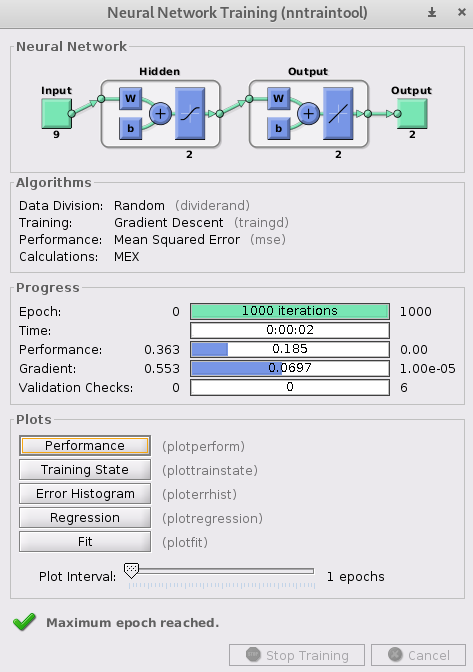

There are several arguments for `train`, and the documentation can be found in this [link](https://www.mathworks.com/help/deeplearning/ref/network.train.html). Note `inputs` and `targets` argument can support more sophisticated arguments, which we won't go over.

- The default loss function is evaluated using the Mean Squared Error

- The default number of epochs is 1000

[trainedNet, trainingRecord] = train(net, inputs, targets)

### Benchmarking the neural network

We can compute the results from the validation set using the following code below:

%ypred = net(inputs)
%error = gsubtract(ypred, targets)
%summary = perform(net, targets, ypred)

### Constructing a deep feed-forward neural network

Up until this point, we have only been dealing with a single hidden layer. What if we wanted to extend our neural network's capacity to handle $L$hidden layers? 

We can generalize the approach we have used to construct the shallow neural network. A crude way of doing this using `for loops` for each layer is shown in the `DNN.mlx` script provided. However, MATLAB has made it easy to construct deep neural networks by simply using the ______ function.

## Issues in training neural networks

While neural networks are really popular for artificial intelligence research and applications, [there are issues with training them](https://machinelearningmastery.com/why-training-a-neural-network-is-hard/). We'll discuss common issues encountered when training neural network and potential strategies to address these issues.

### Initializing values for w and b

Earlier, we initialized our values for w and b to be small random numbers. Is this the best choice for w and b? We discuss 2 alternative cases that are different from our random intiialization of small numbers: if w and b are all zeros and all ones.

#### Setting w and b to be all zeros

We'll go back to our toy dataset with 20 observations and 3 features to illustrate the results when w and b are all zero.

rng(2);

% Toy dataset with 3 features and 20 observations
Xtrain = normrnd(0, 1, [20, 3]);
w = [0, 0, 0]; b = zeros([20, 1]); % Set weights and biases to all equal 0
Z = Xtrain * w' + b;

figure;
plot(Z); hold on; plot(activationFnc(Z, 'Sigmoid')); hold off;
legend({'Z', 'Sigmoid(Z)'}); ylim([-0.1 0.6]);
xlabel('Observations'); ylabel('Z or sigmoid(Z)');

If the values are all zeros, the neural network stops learning the features because there's is no gradient to compute ($\textrm{dW}\;\textrm{and}\;\textrm{db}=0$) during back propagation.

#### Setting w and b to be all ones

Now let's think about what happens when `w` and `b` are set to all ones and we apply the sigmoid activation function. 

The features end up being scaled to logit values in the range [0, 1] by the activation function. Thus, the neural network algorithm becomes the logistic regression classifier. While this is not necessarily a bad thing, a) this is not the nonlinear model we desired, and b) this does slow down our computations, especially with $L$ layer networks. 

#### Symmetry breaking

**Symmetry breaking** is a phenomenon where very small, random fluctuations in a system are able to influence the outcome. By randomly initializing w and b to be small random numbers, we don't break the algorithm from the beginning (ie setting all weights and biases equal to 0) and we allow the neural network to easily approach a better solution through back propagation / gradient descent.

Fortunately for us, MATLAB automatically performs symmetry breaking automatically! Phew.

### Overfitting

Recall that the underlying objective in machine learning is to build a model that balances the model's ability to balance bias and variance. This is known as the **bias-variance tradeoff**. Neural networks are highly nonlinear models with high variance and low bias, and are thus susceptible to overfitting. 

To address this potential issue, one potential solution is to use **regularization (ie LASSO)** in the loss function and gradients. Recall that the regularized term is a function of the coefficients `w` and a tuning factor denoted as lambda$\left(\lambda \right)$. Regularization reduces overfitting by penalizing the weights. 

The following code imposes LASSO regularization on the cross entropy loss function and subsequent back propagation for our shallow neural network:

Note that `lambda` is the LASSO regularization term, and would be another hyperparameter we have to tune if we decide to regularize our neural network. 

#### MATLAB Neural Network Regularization using the Deep Neural Network Toolbox

% 


### Data scaling

While neural networks can capture trends in complex / non-standardized datasets, there are several advantages to train using standardized data:

- We reduce the training time because we're examining a smaller range of values and thus reducing the time it takes for the weights to converge to an optimal value.

- We reduce the change of getting stuck in a local optima when computing the loss due to chance by minimizing the dynamic range of the data.

There are two common methods to scale our data depending on how we wish to interpret each feature: the **Z-score method**, and the **min-max scaling method**. 

The **z-score method** will ensure that each value is scaled to have a mean of 0 and standard deviation of 1. 


$$X_{\textrm{zscore}} =\frac{X_{\textrm{ij}} -\textrm{mean}\left(X_j \right)}{\textrm{std}\left(X_j \right)}$$


While useful, z-score scaling can produce results that don't necessarily reflect true values, especially if our feature is composed of only positive values. 

In those cases, **min-max scaling** can actually be better, where we scale all data points between a value of [0, 1]:


$$X_{\textrm{minmax}} =\frac{X_{\textrm{ij}} -\min \left(X_j \right)}{\max \left(X_j \right)-\min \left(X_j \right)}$$


#### MATLAB Neural Network Regularization using the Deep Neural Network Toolbox

% 


### Determining the best neural network structure to use.

Recall that we've been using a naive approach to determining the number of activation nodes in our neural network, where we assumed two activation nodes are best because we're trying to split the data into two classes. While it's a good starting point, it's another assumption we're imposing on the model.

To determine the best number of activation nodes to use for either a single layer or `L` layers, we need to optimize this hyperparameter in a systematic way. **One way to do so is to run k-fold cross validation, and see which number of activation nodes best improves the accuracy / minimzes the error from the model**. 

## Hyperparameter tuning

Hyperparameter tuning is finding the best set of hyperparameters that will optimize the k-fold cross validation accuracy of our model without overfitting. There are two strategies we can use: a complete grid search, and a random grid search.

### Complete Grid Search

So far, we have discussed the following set of hyperparameters:

- Number of activation nodes for each layer (Number of potential parameters: L layers * n nodes).

- The learning rate (Number of potential parameters: 100, assuming we sample [0.01, 1] in 0.01 increments. Estimate is higher if we want to explore lower / higher values).

- The number of epochs / iterations (Number of potential parameters: 500).

- The activation function (Number of potential parameters: 3).

n = 100 * 100 * 500 * 3;
disp("Number of posible parameter combinations to sample: " + string(n))

There are about $15,000,000$ different possible combinations from 4 parameters to sample, not including the training/test size and optimizing the number of k-folds in cross validation. Yikes. 

A **complete grid search** explores every single combination, which is not feasible on our laptops. Another method that balances the amount of time searching for an optimal model and model performance is a **random grid search**.

### Random Grid Search

A **random grid search** takes in a random combination of hyperparameters to find the best set of hyperparameters to use. There are several benefits to randomized grid search, namely that the search time is decreased by a lot. 

Instead of searching every single combination of parameters, we can chose the number of times we want to run our random search (ie 30 different combinations, as MATLAB does by default) to get the best hyperparameters. Additionally, [Bergestra and Bengio, 2012](http://www.jmlr.org/papers/volume13/bergstra12a/bergstra12a.pdf) found that random search can perform just as well, if not better, than a grid search. 

To run a random grid search, we can use the following code, which uses the script `RandomGridSearchCV` located in the lesson folder. For our purposes, we'll only sample the number of activation nodes and the different activation functions.

% Get distribution of parameters
sampleActivationNodes = [2:100];      % Number of activation nodes to sample
sampleActFnc = [1, 2, 3];             % Activation functions to sample. 1 = log-loss, 2 = relu, 3 = leaky relu.

% Parameters that we're keeping constant
trainingSize = 0.8; kfold = 5; type = "SNN"; iterations = 30;

% Run Random Grid Search with k-fold cross validation
bestParameters = RandomGridSearchCV(iterations, ...
    sampleActivationNodes, sampleActFnc, trainingSize, kfold, type);   

One set of optimal solutions obtained from random grid search found that 82 hidden nodes, a learning rate of 0.91, 64 epochs, and the leaky ReLU resulted in the best model after 30 iterations. We'll use these hyperparameters to benchmark the neural network.

### Hyperparameter tuning in MATLAB's Deep Learning Toolbox

MATLAB does have an argument that allows us to tune the model.

## Summary

In this lecture, we trained a shallow neural network on breast cancer imaging data and evaluated its performance. Additionally, we discussed how training a neural network can be challenging, and some common pitfalls. Finally, we benchmarked the neural network against a logistic regression classifier, and found that the neural network outperformed the logistic regression classifier.

### Built in MATLAB functions covered in this lesson

`fitnet / feedforwardnet:`    Constructs a neural network structure.

`train:                    `Trains the neural network.

`plotperf:                 `Plots the cost curves from the trained neural network.

`crossentropy:             `Computes the cross-entropy cost.

`view:                     `Visualize the neural network structure using the MATLAB GUI. 

`confusionmat:             `Automatically computes a confusion matrix for each class.

`confusionchart`:                         Plots the confusion matrix from `confusionmat`

### List of custom functions

`trainTestSplit:           `Splits an input ($X$) and output ($Y$) dataset into a training $\left(X_{\textrm{train}} {,\;Y}_{\textrm{train}} \right)$ and testing $\left(X_{\textrm{test}} {,\;Y}_{\textrm{test}} \right)$dataset.

`activationFnc:            `Transforms the dataset using a non-linear function.

`costFunction:`                            Computes the cost value from the model.

`crossValidate:`                          Performs k-fold cross validation.

`SNN:`                                               Trains a shallow neural network.

`RandomGridSearchCV:`               Identifies the best hyperparameters using random hyperparameter sampling.

## Useful reading and references

- A [generalized tutorial for learning about neural networks](https://medium.com/datathings/neural-networks-and-backpropagation-explained-in-a-simple-way-f540a3611f5e) that is language-agnostic.

- The [various flavors of neural networks](https://towardsdatascience.com/the-mostly-complete-chart-of-neural-networks-explained-3fb6f2367464), and how they are currently being used in real-world settings.

- Heuristics on deciding [how many hidden layers and activation nodes](https://machinelearningmastery.com/how-to-configure-the-number-of-layers-and-nodes-in-a-neural-network/) to initialize in a neural network.

- [Other activation functions, their usage, and generalizations about pros/cons](https://medium.com/@himanshuxd/activation-functions-sigmoid-relu-leaky-relu-and-softmax-basics-for-neural-networks-and-deep-8d9c70eed91e).

- [Andrew Ng's CS229 deep learning notes ](http://cs229.stanford.edu/notes/cs229-notes-deep_learning.pdf)for a more in-depth understanding of the mathematics and algorithms for constructing neural networks from scratch.

- The [deep learning specialization on Coursera](https://www.coursera.org/specializations/deep-learning) (also taught by Andrew Ng and others at [deeplearning.ai](https://www.deeplearning.ai/)). It consists of 5 courses, all on deep learning and optimizing these models. The course is taught in Python with the specific usage of the `numpy` and `scipy` libraries.

- [Deep Learning](http://www.deeplearningbook.org/) by Ian Goodfellow and Yoshua Bengio - two pioneers in modern deep learning. The book covers 1-2 semester's worth of material for not the basics of constructing and applying deep neural networks, but more cutting-edge techniques in Artificial Intelligence